# Jacobiano geometrico del polso sferico

## Manipolatore di Stanford con $O_6$ = centro polso sferico

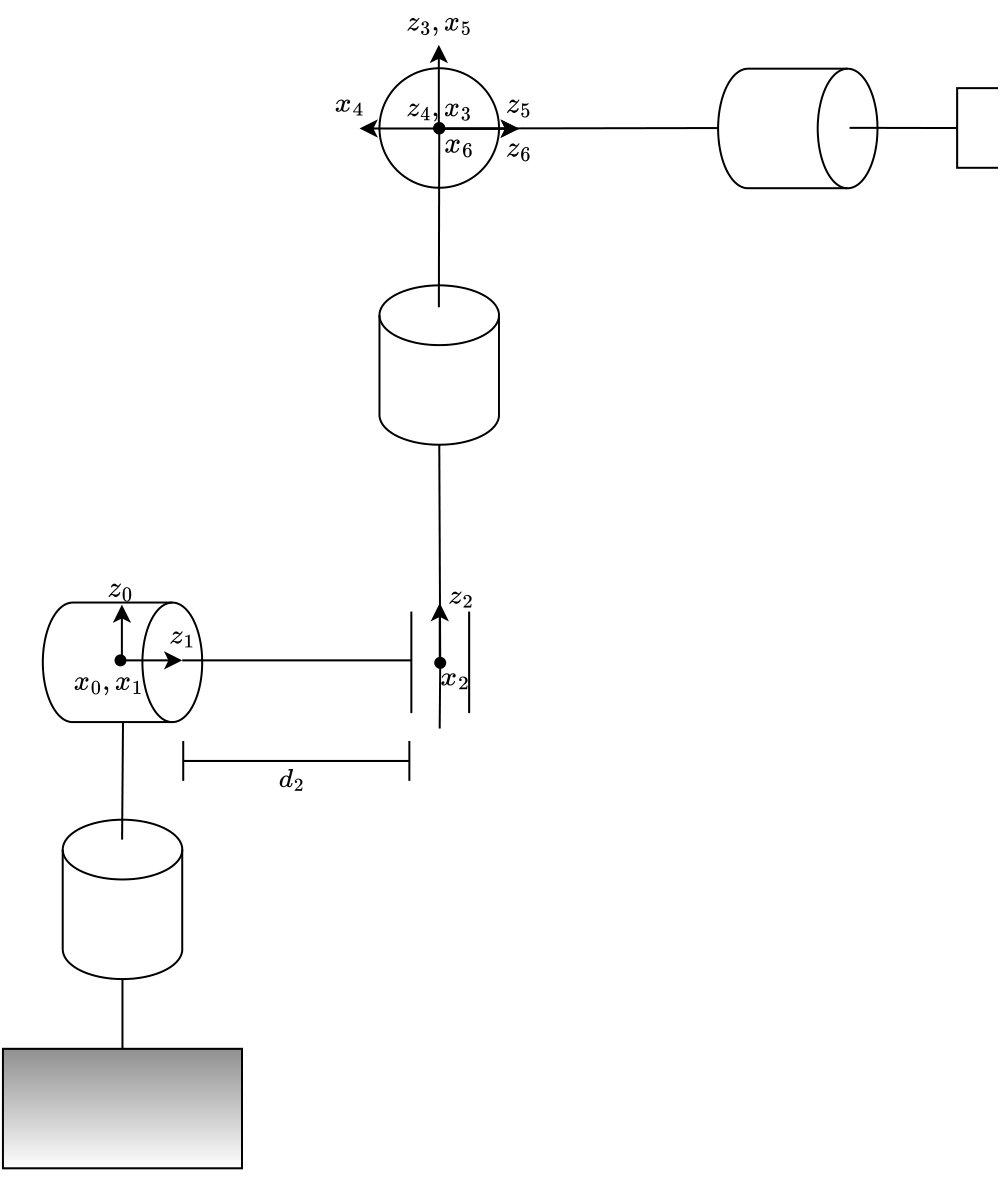

syms q1 q2 q3 q4 q5 q6 d2 real
DHstanford = [0, -pi/2, 0, q1;
              0, pi/2, d2, q2;
              0, 0, q3, 0;
              0, -pi/2, 0, q4;
              0, pi/2, 0, q5;
              0, 0, 0, q6]

$$DHstanford = \left(\begin{array}{cccc} 0 & -\frac{\pi }{2} & 0 & q_{1}\\ 0 & \frac{\pi }{2} & d_{2} & q_{2}\\ 0 & 0 & q_{3} & 0\\ 0 & -\frac{\pi }{2} & 0 & q_{4}\\ 0 & \frac{\pi }{2} & 0 & q_{5}\\ 0 & 0 & 0 & q_{6} \end{array}\right)$$

J = simplify(jacGeom(DHstanford, [1,1,0,1,1,1]))

$$J = \begin{array}{l} \left(\begin{array}{cccccc} -d_{2}\,\cos\left(q_{1}\right)-q_{3}\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right) & q_{3}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right) & \sigma_{2} & 0 & 0 & 0\\ q_{3}\,\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)-d_{2}\,\sin\left(q_{1}\right) & q_{3}\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right) & \sigma_{1} & 0 & 0 & 0\\ 0 & -q_{3}\,\sin\left(q_{2}\right) & \cos\left(q_{2}\right) & 0 & 0 & 0\\ 0 & -\sin\left(q_{1}\right) & 0 & \sigma_{2} & -\cos\left(q_{4}\right)\,\sin\left(q_{1}\right)-\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\,\sin\left(q_{4}\right) & \cos\left(q_{1}\right)\,\cos\left(q_{5}\right)\,\sin\left(q_{2}\right)-\sin\left(q_{5}\right)\,\left(\sin\left(q_{1}\right)\,\sin\left(q_{4}\right)-\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\,\cos\left(q_{4}\right)\right)\\ 0 & \cos\left(q_{1}\right) & 0 & \sigma_{1} & \cos\left(q_{1}\right)\,\cos\left(q_{4}\right)-\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)\,\sin\left(q_{4}\right) & \sin\left(q_{5}\right)\,\left(\cos\left(q_{1}\right)\,\sin\left(q_{4}\right)+\cos\left(q_{2}\right)\,\cos\left(q_{4}\right)\,\sin\left(q_{1}\right)\right)+\cos\left(q_{5}\right)\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\\ 1 & 0 & 0 & \cos\left(q_{2}\right) & \sin\left(q_{2}\right)\,\sin\left(q_{4}\right) & \cos\left(q_{2}\right)\,\cos\left(q_{5}\right)-\cos\left(q_{4}\right)\,\sin\left(q_{2}\right)\,\sin\left(q_{5}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\\ \sigma_{2}=\cos\left(q_{1}\right)\,\sin\left(q_{2}\right) \end{array}$$

Si ha quindi $\mathbf J(q_1, \dots, q_5) = \pmatrix{\mathbf J_{11} & 0\cr \mathbf J_{21} & \mathbf J_{22}}$ per cui $\det \mathbf J(q_1, \dots, q_5) = \det \mathbf J_{11} \det \mathbf J_{22}  $. 

detJ = simplify(det(J))

$$detJ = {q_{3}}^{2}\,\sin\left(q_{2}\right)\,\sin\left(q_{5}\right)$$

$\det \mathbf J_{11} (q_1, \dots, q_3) = 0$ fornisce le singolarità della struttura portante.

J11 = J(1:3, 1:3)

$$J11 = \left(\begin{array}{ccc} -d_{2}\,\cos\left(q_{1}\right)-q_{3}\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right) & q_{3}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right) & \cos\left(q_{1}\right)\,\sin\left(q_{2}\right)\\ q_{3}\,\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)-d_{2}\,\sin\left(q_{1}\right) & q_{3}\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right) & \sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\\ 0 & -q_{3}\,\sin\left(q_{2}\right) & \cos\left(q_{2}\right) \end{array}\right)$$

detJ11 = simplify(det(J11))

$$detJ11 = -{q_{3}}^{2}\,\sin\left(q_{2}\right)$$

$\det \mathbf J_{22} (q_1, \dots, q_5) = 0$ fornisce le singolarità del polso sferico.

J22 = J(4:6, 4:6)

$$J22 = \left(\begin{array}{ccc} \cos\left(q_{1}\right)\,\sin\left(q_{2}\right) & -\cos\left(q_{4}\right)\,\sin\left(q_{1}\right)-\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\,\sin\left(q_{4}\right) & \cos\left(q_{1}\right)\,\cos\left(q_{5}\right)\,\sin\left(q_{2}\right)-\sin\left(q_{5}\right)\,\left(\sin\left(q_{1}\right)\,\sin\left(q_{4}\right)-\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\,\cos\left(q_{4}\right)\right)\\ \sin\left(q_{1}\right)\,\sin\left(q_{2}\right) & \cos\left(q_{1}\right)\,\cos\left(q_{4}\right)-\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)\,\sin\left(q_{4}\right) & \sin\left(q_{5}\right)\,\left(\cos\left(q_{1}\right)\,\sin\left(q_{4}\right)+\cos\left(q_{2}\right)\,\cos\left(q_{4}\right)\,\sin\left(q_{1}\right)\right)+\cos\left(q_{5}\right)\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\\ \cos\left(q_{2}\right) & \sin\left(q_{2}\right)\,\sin\left(q_{4}\right) & \cos\left(q_{2}\right)\,\cos\left(q_{5}\right)-\cos\left(q_{4}\right)\,\sin\left(q_{2}\right)\,\sin\left(q_{5}\right) \end{array}\right)$$

detJ22 = simplify(det(J22))

$$detJ22 = -\sin\left(q_{5}\right)$$

Si ha quindi singolarità per $q_5 = 0, \pi$.

## Jacobiano geometrico del polso sferico

DHpolso = [0, -pi/2, 0, q4;
              0, pi/2, 0, q5;
              0, 0, 0, q6]

$$DHpolso = \left(\begin{array}{cccc} 0 & -\frac{\pi }{2} & 0 & q_{4}\\ 0 & \frac{\pi }{2} & 0 & q_{5}\\ 0 & 0 & 0 & q_{6} \end{array}\right)$$

tList = cinDirDH(DHpolso);
T = simplify(tList{4})

$$T = \left(\begin{array}{cccc} \cos\left(q_{4}\right)\,\cos\left(q_{5}\right)\,\cos\left(q_{6}\right)-\sin\left(q_{4}\right)\,\sin\left(q_{6}\right) & -\cos\left(q_{6}\right)\,\sin\left(q_{4}\right)-\cos\left(q_{4}\right)\,\cos\left(q_{5}\right)\,\sin\left(q_{6}\right) & \cos\left(q_{4}\right)\,\sin\left(q_{5}\right) & 0\\ \cos\left(q_{4}\right)\,\sin\left(q_{6}\right)+\cos\left(q_{5}\right)\,\cos\left(q_{6}\right)\,\sin\left(q_{4}\right) & \cos\left(q_{4}\right)\,\cos\left(q_{6}\right)-\cos\left(q_{5}\right)\,\sin\left(q_{4}\right)\,\sin\left(q_{6}\right) & \sin\left(q_{4}\right)\,\sin\left(q_{5}\right) & 0\\ -\cos\left(q_{6}\right)\,\sin\left(q_{5}\right) & \sin\left(q_{5}\right)\,\sin\left(q_{6}\right) & \cos\left(q_{5}\right) & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Jpolso = simplify(jacGeom(DHpolso, [1,1,1]))

$$Jpolso = \left(\begin{array}{ccc} 0 & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & 0\\ 0 & -\sin\left(q_{4}\right) & \cos\left(q_{4}\right)\,\sin\left(q_{5}\right)\\ 0 & \cos\left(q_{4}\right) & \sin\left(q_{4}\right)\,\sin\left(q_{5}\right)\\ 1 & 0 & \cos\left(q_{5}\right) \end{array}\right)$$

Per trovare le singolarità si considerano i casi in cui lo Jacobiano perde di rango, ovvero:

Jp = Jpolso(4:6, :)

$$Jp = \left(\begin{array}{ccc} 0 & -\sin\left(q_{4}\right) & \cos\left(q_{4}\right)\,\sin\left(q_{5}\right)\\ 0 & \cos\left(q_{4}\right) & \sin\left(q_{4}\right)\,\sin\left(q_{5}\right)\\ 1 & 0 & \cos\left(q_{5}\right) \end{array}\right)$$

simplify(det(Jp))

$$ans = -\sin\left(q_{5}\right)$$